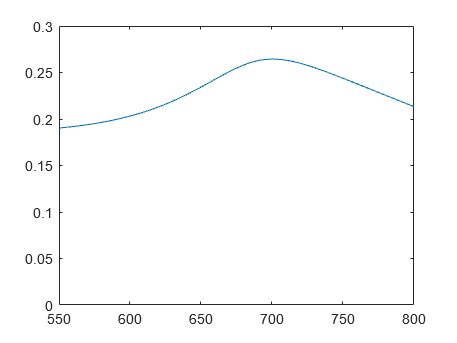

for l = 1:500
    Temp(l) = 400 + l*1;
    T3(1) = Temp(l);

    for  k = 2 : MAXvol3/dV
    
        V3(k) = (k-1)*dV + MAXvol + MAXvol2;
        eta3(k-1) = b0+b1*T3(k-1)+b2*X3(k-1)+b3*(T3(k-1)^2)+b4*(X3(k-1)^2)+b5*(T3(k-1)^3)+b6*(X3(k-1)^3);
        fugnh3(k-1) = 0.1438996 +((0.2028538E-2)*T3(k-1))-((0.448762E-3)*P(k-1))-((0.1142945E-5)*T3(k-1)^2)+((0.2761216E-6)*P(k-1));
        fugn2(k-1) =  0.93431737 + ((0.3101804E-3)*T3(k-1)) + ((0.295896E-3)*P(k-1)) - ((0.2707279E-6)*(T3(k-1))^2) + (0.477507E-6*(P(k-1))^2);
        fugh2(k-1) = exp( exp(-3.8402*T3(k-1)^0.125+0.541)*P(k-1) - exp(-0.1263*T3(k-1)^0.5-15.98)*P(k-1)^2 + 300*exp(-0.011901*T3(k-1)-5.941)*exp(P(k-1)/300));
        ynh3_3(k-1) = (YNH3 + 2*X3(k-1)*YN2)/(1-2*X3(k-1)*YN2);
        yn2_3(k-1) = (YN2*(1-X3(k-1)))/(1-2*X3(k-1)*YN2);
        yh2_3(k-1) = (YH2 - 3*X3(k-1)*YN2)/(1-2*X3(k-1)*YN2);
        yar_3(k-1) = YAr/(1-2*X3(k-1)*YN2);
        anh3(k-1) = ynh3_3(k-1)*fugnh3(k-1)*P(k-1);
        an2(k-1) = yn2_3(k-1)*fugn2(k-1)*P(k-1);
        ah2(k-1) = yh2_3(k-1)*fugh2(k-1)*P(k-1);
        K3(k-1) = 10^(-2.691122*log10(T3(k-1))-(5.519265*10^(-5))*T3(k-1)+(1.848863*10^(-7))*T3(k-1)^2+(2001.6/T3(k-1))+2.6899);
        Kequil(k-1) = sqrt((anh3(k-1)^2)/(an2(k-1)*ah2(k-1)^3));
        Xequil(k-1) = Kequil(k-1)/(1+Kequil(k-1));
        k2(k-1) = k0*exp(-E2/(R*T3(k-1)));
        Rnh3_3(k-1) = 2*k2(k-1)*(K3(k-1)^2*an2(k-1)*((ah2(k-1)^3)/(anh3(k-1)^2))^alpha-((anh3(k-1)^2)/(ah2(k-1)^3))^(1-alpha)); %kmol/m3.hr
        dHr(k-1) = 4.184*(-(P(k-1))*(0.54526+(840.609)/(T3(k-1))+(459.734E6)/(T3(k-1)^3))-5.34685*T3(k-1)-(0.2525E-3)*T3(k-1)^2+(1.69167E-6)*T3(k-1)^3-9157.09); %kJ/kmol
        CpH2(k-1) = 4.184*(6.952+((-0.04567E-2)*(T3(k-1)))+((0.09563E-5)*(T3(k-1))^2)+((-0.2079E-9)*(T3(k-1))^3));
        CpN2(k-1) = 4.184*(6.903+((-0.03753E-2)*(T3(k-1)))+((0.193E-5)*(T3(k-1))^2)+((-0.6861E-9)*(T3(k-1))^3));
        CpAr(k-1) = 4.184*(4.75);
        CpNH3(k-1) = 4.184*(6.5846 - T3(k-1)*(0.61251E-2) + (T3(k-1)^2)*(0.23663E-5)-(T3(k-1)^3)*(1.5981E-9)+96.1678-0.067571*P(k-1)+T3(k-1)*(-0.2225+(1.6847E-4)*(P(k-1)))+(T3(k-1)^2)*((1.289E-4)-(1.0095E-7)*P(k-1)));
        Cpmix(k-1) = yh2_3(k-1)*CpH2(k-1) + ynh3_3(k-1)*CpNH3(k-1) + yn2_3(k-1)*CpN2(k-1) + CpAr(k-1)*yar_3(k-1);
        Cpmix2(k-1) = 35.31 + 0.02*T3(k-1) + 0.00000694*T3(k-1)^2-0.0056*(P(k-1)*101.325)+0.000014*(P(k-1)*101.325)*T3(k-1); %kJ/kmol
        dXdV = (eta3(k-1) * Rnh3_3(k-1) )/(2*F2N2);
        dTdV = (-(dHr(k-1))*eta3(k-1)*Rnh3_3(k-1))/(F2TOTAL*Cpmix(k-1));
        %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
        X3(k) = X3(k-1) + dXdV*dV;
        T3(k) = T3(k-1) + dTdV*dV;
        %P(i) = P(i-1) + dPdL*dL
    end
    Xout(l) = X3(1,end);
    Tin(l) = T3(1,1);
    Tout(l) = T3(1,end);
end

plot(Tin,Xout)
ylim([0,0.3])
xlim([550,800])

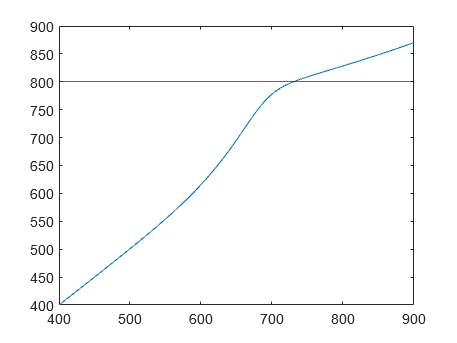


plot(Tin,Tout)
yline(800)